disp('Metoda siecznych')

Metoda siecznych



% funkcja
f = @(x) 2 * exp(-((x/3-1).^2)).^2 + 5*sqrt(x) - 8;

% Funkcja metody siecznych
function [tableResults, errors, num_iter] = secant_method(f, x_span, delta, x_ref)
    x_prev = x_span(1);
    x_curr = x_span(2);
    k = 1;
    iter_data = [];

    % Warunek while: abs(x_curr - x_ref) >= delta
    while abs(x_curr - x_ref) >= delta
        x_next = x_curr - ((x_curr - x_prev) / (f(x_curr) - f(x_prev))) * f(x_curr);
        modulus_f = abs(f(x_next));
        modulus_x = abs(x_next - x_ref);  % Zmiana warunku zatrzymania na różnicę między x_next a x_ref
        f_val = f(x_next);
        iter_data = [iter_data; k, x_next, f_val, modulus_f, modulus_x];
        
        if abs(x_next - x_ref) < delta
            break;
        end
        
        x_prev = x_curr;
        x_curr = x_next;
        k = k + 1;
    end

    tableResults = array2table(iter_data, 'VariableNames', {'Iteration', 'x', 'f(x)', 'f(x)_modulus', 'x_modulus'});
    errors = abs(iter_data(:, 2) - x_ref);  % Błąd bezwzględny względem x_ref
    num_iter = k;
end

% Obliczenie miejsca zerowego za pomocą fzero jako punkt odniesienia
x_span = [1, 10];
x_ref = fzero(f, x_span);  % <- Punkt odniesienia
disp(['Miejsce zerowe obliczone za pomocą fzero: ', num2str(x_ref)]);

Miejsce zerowe obliczone za pomocą fzero: 1.7397



% Przykład użycia funkcji secant_method i wyświetlenie wyników
delta = 10^-10; % Przykładowa wartość delta

[tableResults_secant, errors_secant, num_iter_secant] = secant_method(f, x_span, delta, x_ref);  % <- Wywołanie z x_ref
disp(tableResults_secant);

    Iteration             x                       f(x)             f(x)_modulus    x_modulus 
    _________    ____________________    ______________________    ____________    __________

        1          2.9621+0i                 2.6048+0i                  2.6048         1.2224
        2        -0.55876+0i                -7.8801+3.7375i             8.7215         2.2984
        3           2.186-0.27665i           1.1544-0.64227i             1.321        0.52515
        4          1.8275-0.21997i          0.25115-0.57643i           0.62876        0.23687
        5          1.7466+0.018691i        0.018696+0.050044i         0.053422       0.019933
        6           1.739+2.4807e-05i    -0.0017596+6.6558e-05i      0.0017609     0.00065637
        7          1.7397+1.6476e-06i    1.8032e-06+4.4198e-06i     4.7735e-0


% Rysowanie wykresu metody siecznych
figure;
fplot(f, [1 10]); % Ustawienie pełnego zakresu wykresu
xlabel('x');
ylabel('f(x)');
title('Metoda siecznych');
grid on;
hold on;
for i = 1:height(tableResults_secant)
    plot(tableResults_secant.x(i), real(tableResults_secant.('f(x)')(i)), 'ro');
    text(tableResults_secant.x(i), real(tableResults_secant.('f(x)')(i)), num2str(i), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end

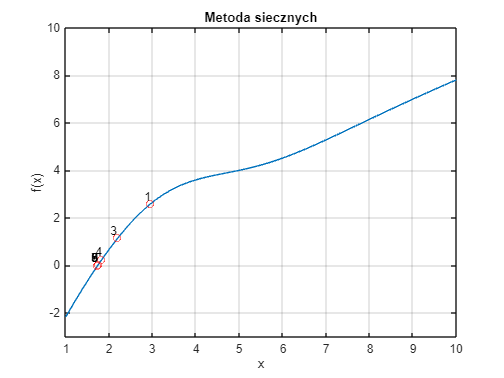

axis([1 10 -3 10]); % Ustawienie pełnego zakresu osi
hold off;

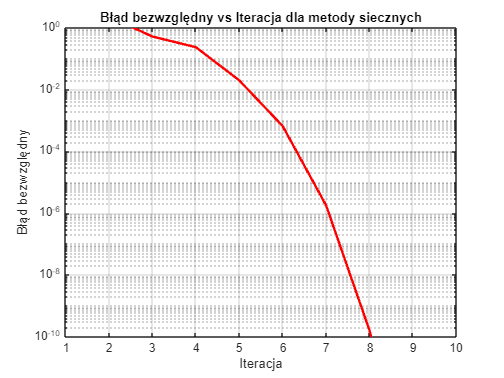


% Rysowanie wykresu błędów bezwzględnych dla metody siecznych
figure;
semilogy(1:height(tableResults_secant), errors_secant, 'r-', 'LineWidth', 2);
xlabel('Iteracja');
ylabel('Błąd bezwzględny');
title('Błąd bezwzględny vs Iteracja dla metody siecznych');
grid on;
xlim([1, max(10, height(tableResults_secant))]); % Ustawienie zakresu osi X
ylim([10^-10, 1]); % Ustawienie zakresu osi Y
hold off;


% Zakres wartości delta
deltas = logspace(-15, -1, 15);

% Wyznaczenie liczby iteracji dla różnych wartości delta
num_iterations_secant = zeros(length(deltas), 1);
for j = 1:length(deltas)
    epsilon = deltas(j);
    [~, ~, num_iter] = secant_method(f, [1, 10], epsilon, x_ref); % Przedział do obliczeń może zostać jako [1, 2]
    num_iterations_secant(j) = num_iter;
end

% Wyświetlenie wyników w tabeli
iterations_table_secant = table(deltas', num_iterations_secant, 'VariableNames', {'Delta', 'Metoda siecznych iteracje'});
disp(iterations_table_secant);

    Delta     Metoda siecznych iteracje
    ______    _________________________

     1e-15                9            
     1e-14                9            
     1e-13                9            
     1e-12                9            
     1e-11                9            
     1e-10                9            
     1e-09                8            
     1e-08                8            
     1e-07                8            
     1e-06                8            
     1e-05                7            
    0.0001                7            
     0.001                6            
      0.01                6            
       0.1                5            



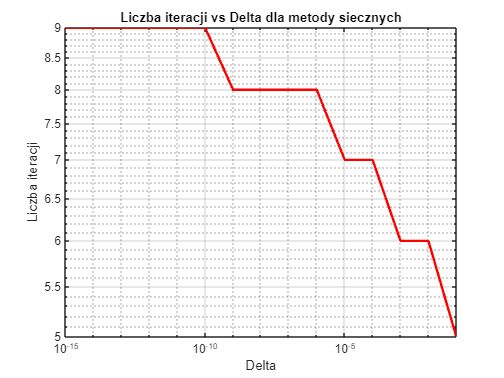


% Rysowanie wykresu liczby iteracji w zależności od delta dla metody siecznych
figure;
loglog(deltas, num_iterations_secant, 'r-', 'LineWidth', 2);
xlabel('Delta');
ylabel('Liczba iteracji');
title('Liczba iteracji vs Delta dla metody siecznych');
grid on;
axis tight; % Automatyczne dopasowanie osi
hold off;